## Grayscale image conversion with conventional Stochastic Computing (SC) multiplier and Parallel Counter

**Created by: Yang Yang Lee

**Date: 12th Dec 2024

**Revision: 1.0

This example code will simulate the conventional SC multiply-accumulate (MAC) circuit with AND gate array and binary full adder (FA) as a simple parallel counter. The resultant data stream is of binary value, summing all the stream value will recover the exact magnitude of the MAC output. In the end, it computes the mean absolute error (MAE) to see the errors relative to the binary computed grayscale image.

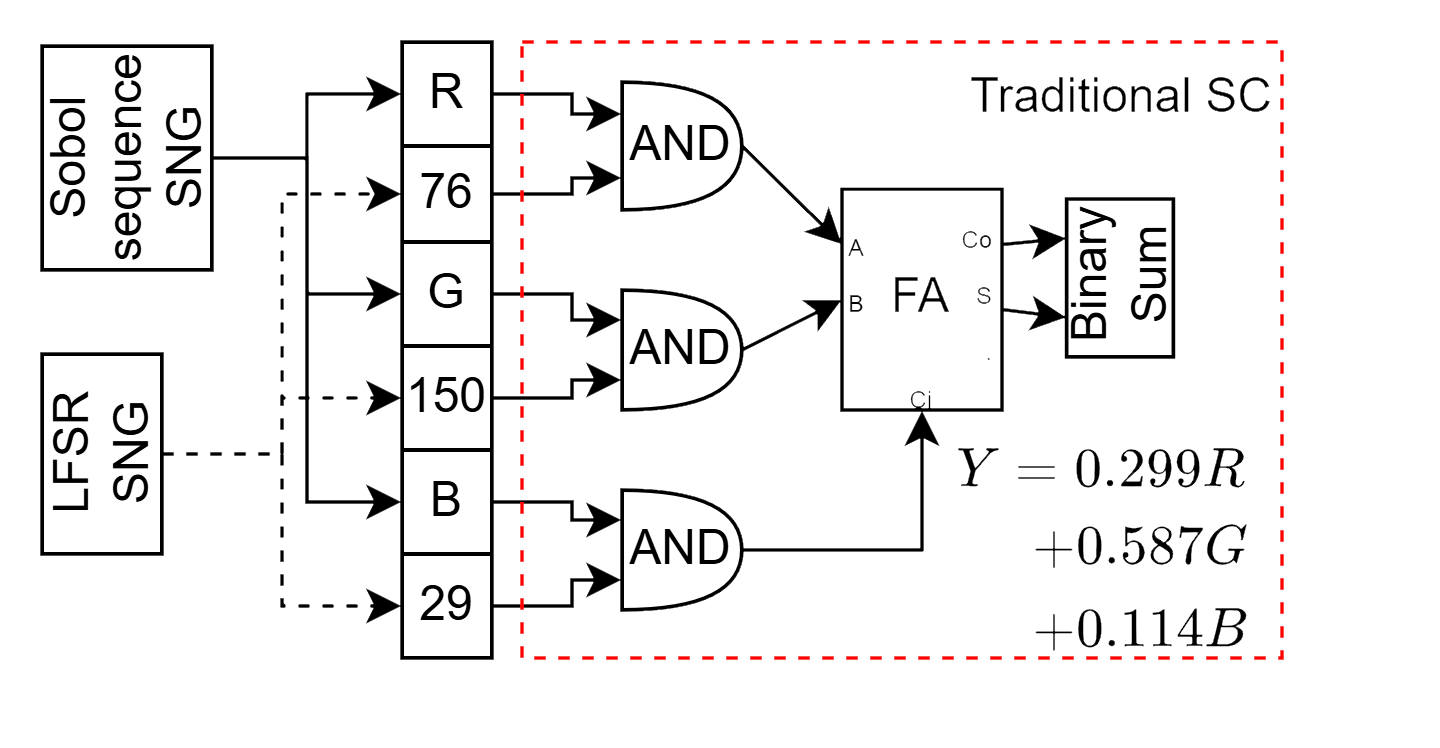

Firstly, define all the necessary functions to be used, 

function output = WBC(x)
    %this function is to convert LFSR or Sobol sequence into MUX select
    %input binary stream, the input is expected to have dimensions of
    %(runlength, resolution), e.g. (255,8)
    output = int8.empty(0,length(x));   %initialize array for speed
    for i = 1:length(x)                 %weighted binary converter to feed to MUX-based SNG
        output(i) = find(x(i,:),1)-1;   %return the position of the first non-zero element
    end
end
function output = MUXSNG(input, sel) 
    %this function is to generate bitstream from a binary input
    %sel is a stream of MUX select input wuth 255 clocks length
    %it could be LFSR sequence or Sobol sequence, passed through WGC
    bitstream = zeros([8,255],'logical');
    for i=1:8
        bitstream(i,:) = bitget(input,9-i)==1;
    end
    %vector computing by rearranging selected bitstreams and select the
    %diagonal components to mimic multiplexer operation. "sel+1" is because
    %the MATLAB array indexing starts from 1
    output = diag(bitstream(sel+1,:))'; 
end
function output = grayscale_SC_FA(R, G, B, Sobol8sel, LFSR8sel)
    %this is the traditional SC with AND gate array and FA adder.
    persistent WRbit WGbit WBbit %use persistent memory to avoid repeated computation to speed up simulation
    if isempty(WRbit) 
        %these bitstreams only need to be computed for once
        WRbit = MUXSNG(76, LFSR8sel); %0.299*255 ~ 76
        WGbit = MUXSNG(150, LFSR8sel); %0.587*255 ~ 150
        WBbit = MUXSNG(29, LFSR8sel); %0.114*255 ~ 29
    end
    Rbit = MUXSNG(R, Sobol8sel);
    Gbit = MUXSNG(G, Sobol8sel);
    Bbit = MUXSNG(B, Sobol8sel);
    YR = Rbit & WRbit; %AND gate
    YG = Gbit & WGbit;
    YB = Bbit & WBbit;
    output = YR+YG+YB; % binary add
end
function mae = calMAE(orgSig,recSig,varargin)
    if isempty(varargin)
        boun = 0;
    else boun = varargin{1};
    end
    if size(orgSig,2)==1       % if signal is 1-D
        orgSig = orgSig(boun+1:end-boun,:);
        recSig = recSig(boun+1:end-boun,:);
    else                       % if signal is 2-D or 3-D
        orgSig = orgSig(boun+1:end-boun,boun+1:end-boun,:);
        recSig = recSig(boun+1:end-boun,boun+1:end-boun,:);
    end
    absErr = norm(orgSig(:)-recSig(:),1);
    mae = absErr/length(orgSig(:));
end

Then, prepare the random number generators (RNGs) and execute the functions:

clear;
%setup LFSR
runlength = 255;
LFSR8 = [1 0 0 0 0 0 0 0];
for i = 1:runlength-1 %linear feedback shift register
    LFSR8(i+1,1) = xor(xor(LFSR8(i,8),LFSR8(i,6)),xor(LFSR8(i,5),LFSR8(i,4)));
    LFSR8(i+1,2) = LFSR8(i,1);    LFSR8(i+1,3) = LFSR8(i,2);    LFSR8(i+1,4) = LFSR8(i,3);
    LFSR8(i+1,5) = LFSR8(i,4);    LFSR8(i+1,6) = LFSR8(i,5);    LFSR8(i+1,7) = LFSR8(i,6);
    LFSR8(i+1,8) = LFSR8(i,7);
end
LFSR8a = flip(LFSR8,2); %permute the LFSR bit, will be used for more advanced SC workload
count = 1;
Sobol8 = [0 0 0 0 0 0 0 1];
for i = 1:runlength
    Sobol8(i,8) = mod(count,2)>=1;    Sobol8(i,7) = mod(count,4)>=2;
    Sobol8(i,6) = mod(count,8)>=4;    Sobol8(i,5) = mod(count,16)>=8;
    Sobol8(i,4) = mod(count,32)>=16;  Sobol8(i,3) = mod(count,64)>=32;
    Sobol8(i,2) = mod(count,128)>=64; Sobol8(i,1) = mod(count,256)>=128;
    count = count + 1;
end
Sobol8 = flip(Sobol8,2);%flip LSB to MSB before feeding to WBC
% start processing RGB image
%img = imread("<your path to jpg image>");
LFSR8sel = WBC(LFSR8);% input SNG sel (LFSR)
Sobol8sel = WBC(Sobol8);% input SNG sel (sobol)
img_gray = zeros(size(img,1),size(img,2),length(LFSR8),"int8"); %initialize array for speed
%simulating SC grayscale conversion pixel-by-pixel
rows = size(img,1); cols = size(img,2);

It also use "multiWaitbar" for showing prgresses, please get it from MATLAB file exchange, the one developed by Ben Tordoff. Otherwise, just comment out.

multiWaitbar('CloseAll');
multiWaitbar('Converting to grayscale...', 0); % to reduce programmer's anxiety
for i = 1:rows
    %use "parfor" to accelerate for loop with multithreading, need parallel
    %computing toolbox. Otherwise, just use for loop
    imgrow = img(i,:,:);    %extract image row for speed
    multiWaitbar('Converting to grayscale...', i/size(img,1));
    parfor j = 1:cols
        R = imgrow(1,j,1); G = imgrow(1,j,2); B = imgrow(1,j,3);
        gray = grayscale_SC_FA(R, G, B, Sobol8sel, LFSR8sel);
        img_gray(i,j,:) = permute(gray,[1 3 2]); %convert bitstream to 3rd dimension and save
    end
end
multiWaitbar('CloseAll');

The SC grayscale image conversion is finished here. The variable img_gray is of 3 dimensions, (row, column, runlength), summing the 3rd dimension will recover the grayscale magnitude

img_gray_flatten = sum(img_gray,3);
img_gray_flatten = cast(img_gray_flatten,'like',img);
img_gray_binary = rgb2gray(img); %binary computing

Here is to visually compare the SC grayscale image to the binary computed image.

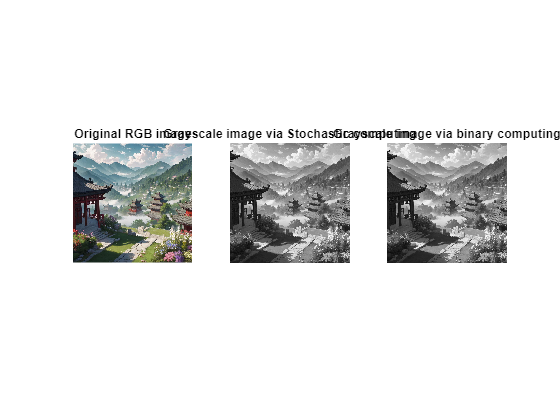

subplot(1,3,1)
imshow(img)
title('Original RGB image')
subplot(1,3,2)
imshow(img_gray_flatten);
title('Grayscale image via Stochastic computing')
subplot(1,3,3)
imshow(img_gray_binary);
title('Grayscale image via binary computing')

Finally, compare the MAE of SC grayscale image.

mae = calMAE(cast(img_gray_flatten,'single')/255,cast(img_gray_binary,'single')/255);
formatSpec = 'MAE is %.2fe-3\n';
fprintf(formatSpec,mae*1000)

MAE is 9.59e-3
